**Q1)**

**a)**

close all;
clc;

%given data
m = 0.1; % mass(kg)
R = 0.02; % radius(m)
J = 1e-5; % moment of inertia(kg m^2)
L = 1; % length of the rod(m)
d = 0.05; %lever arm length(m)
g = 9.8; % gravity(m/s^2)

% Initial conditions
r = 0.25; %position(m)
r_dot = 0; %velocity(m/s)
r_ddot = 0; %acceleration(m/s^2)
theta = 0; %control input(rad)

%end time
dt =0.01;
t_final = 25;
time = 0:dt:t_final;

% reference position
r_ref = @(t) 0.25 * sin(t) + 0.25;

r_sim_data = zeros(1, length(time));
theta_sim_data = zeros(1, length(time));

% Error
e_int = 0; % Integral of the error
e_prev = 0; % Previous error 

% PID Gains
Kp =135;
Ki = 10;
Kd = 45; 

for i = 1:length(time)
    
    t = time(i);

    %reference position at current time
    r_ref_update = r_ref(t);

    % Error calculations
    e = r_ref_update - r; % Proportional
    e_int = e_int + e * dt; % Integral
    e_der = (e - e_prev) / dt; % Derivative

    % PID controller
    theta = Kp * e + Ki * e_int + Kd * e_der;

    % System
    alpha = (d / L) * theta;

    %EOM
    r_ddot = ((m*g*sin(alpha)) + (m*r_dot^2)) / ((J/(R^2)) + m); 

    %position and velocity
    r_dot = r_dot + r_ddot * dt;
    r = r + r_dot * dt; 

    r_sim_data(i) = r;
    theta_sim_data(i) = theta;

    %In degree
    % theta_sim_data_degree(i)=rad2deg(theta);

    %previous error
    e_prev = e;
end

**Q1)**

**Part c)**

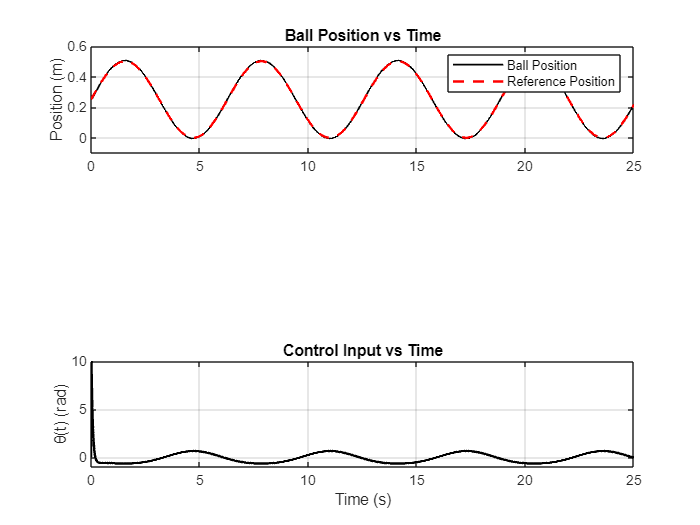

% Plots
subplot(3, 1, 1);
plot(time, r_sim_data, 'k-', 'LineWidth', 1);
hold on;
plot(time, arrayfun(r_ref, time), 'r--', 'LineWidth', 1.5);
legend('Ball Position','Reference Position');
ylabel('Position (m)');
title('Ball Position vs Time');
ylim([-0.1 0.6]);
grid on;

% subplot(3, 1, 2);
% plot(time, theta_sim_data_degree, 'k-', 'LineWidth', 1.5);
% xlabel('Time (s)');
% ylabel('θ(t) (degree)');
% title('Control Input vs Time');
% grid on;

subplot(3, 1, 3);
plot(time, theta_sim_data, 'k-', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('θ(t) (rad)');
title('Control Input vs Time');
ylim([-1 10]);
grid on;

**Q1)**

**Part b)**

**PID Gains**

**Kp =125**

**Ki=15**

**Kd=40**

**Q2)**

**Part a)**

% State-space
A = [0 1; 0 0];
B = [0; g*d/(L*(J/R^2 + m))];
C = [1 0];
D = 0;

% pole locations
P1 = [-1, -2];
P2 = [-2+2i, -2-2i];

% pole placement
K1 = place(A, B, P1);
K2 = place(A, B, P2);

t_final = 25;
dt = 0.01;
t = 0:dt:t_final;

% Initial conditions(position and velocity)
x0 = [0.25; 0];


r_sim1 = zeros(length(t), 1);
r_sim2 = zeros(length(t), 1);
theta_sim1 = zeros(length(t), 1);
theta_sim2 = zeros(length(t), 1);

% for p1
x = x0;
for i = 1:length(t)
    theta = -K1*x;
    x_dot = A*x + B*theta;
    x = x + x_dot * dt;
    r_sim1(i) = x(1);
    theta_sim1(i) = theta;
end

% for p2
x = x0;
for i = 1:length(t)
    theta = -K2*x;
    x_dot = A*x + B*theta;
    x = x + x_dot * dt;
    r_sim2(i) = x(1);
    theta_sim2(i) = theta;
end

%plots 
figure;
subplot(2, 1, 1);
plot(t, r_sim1, 'b');
title('Ball Position with Poles at [-1, -2]');
xlabel('Time (s)');
ylabel('Position (m)');
grid on;

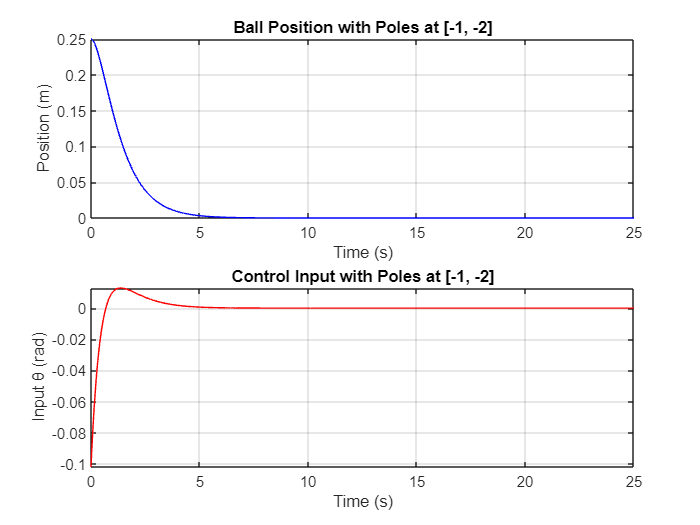

subplot(2, 1, 2);
plot(t, theta_sim1, 'r');
title('Control Input with Poles at [-1, -2]');
xlabel('Time (s)');
ylabel('Input θ (rad)');
grid on;

figure;
subplot(2, 1, 1);
plot(t, r_sim2, 'b');
title('Ball Position with Poles at [-2+2i, -2-2i]');
xlabel('Time (s)');
ylabel('Position (m)');
ylim([-0.1 0.3])
grid on;

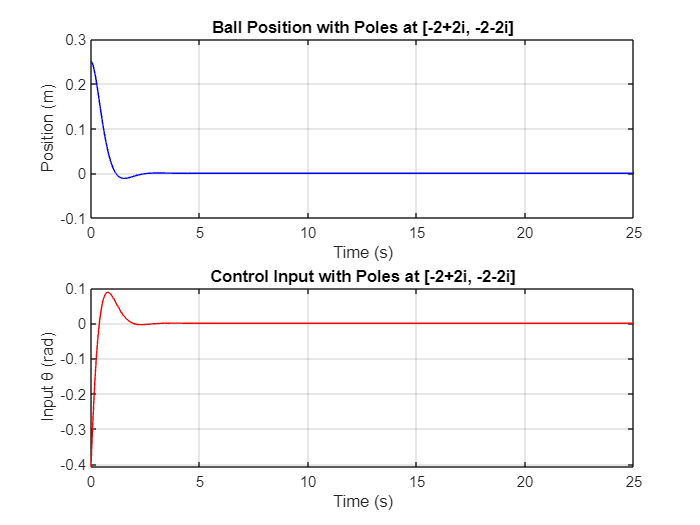

subplot(2, 1, 2);
plot(t, theta_sim2, 'r');
title('Control Input with Poles at [-2+2i, -2-2i]');
xlabel('Time (s)');
ylabel('Input θ (rad)');
grid on;

**Q2)**

**Part b)**

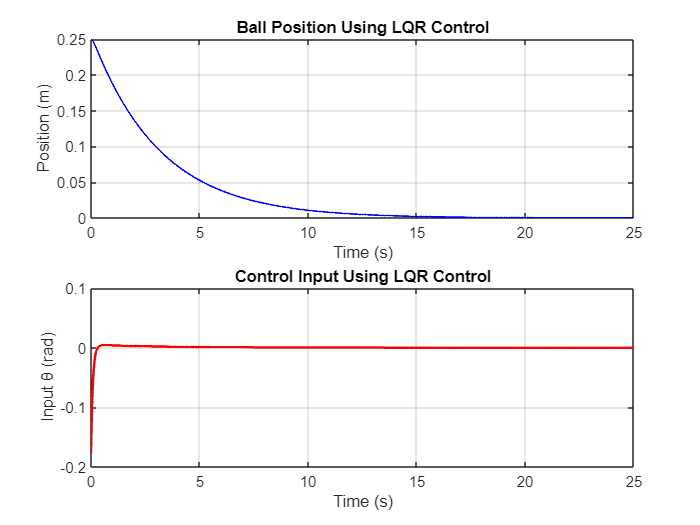

% LQR gain matrices
Q = [1 0; 0 10];
R = 2;

% LQR controller gain
[K, S, e] = lqr(A, B, Q, R);

% Initial conditions
% initial position and velocity
x0 = [0.25; 0]; 
% Initialize state vector
x = x0;


r_data = zeros(size(time));
theta_data = zeros(size(time));

for i = 1:length(time)
    theta = -K * x;
    x_dot = A * x + B * theta;
    x = x + x_dot * dt;
    r_data(i) = x(1);
    theta_data(i) = theta;
end

% Plot
figure;
subplot(2, 1, 1);
plot(time, r_data, 'b', 'LineWidth', 1);
title('Ball Position Using LQR Control');
xlabel('Time (s)');
ylabel('Position (m)');
grid on;

subplot(2, 1, 2);
plot(time, theta_data, 'r', 'LineWidth', 1.5);
title('Control Input Using LQR Control');
xlabel('Time (s)');
ylabel('Input θ (rad)');
ylim([-0.2 0.1])
grid on;

**Q3)Permanent Magnet DC Motor(PMDC)**

- **The Reference otor speed is 25 rad/sec**

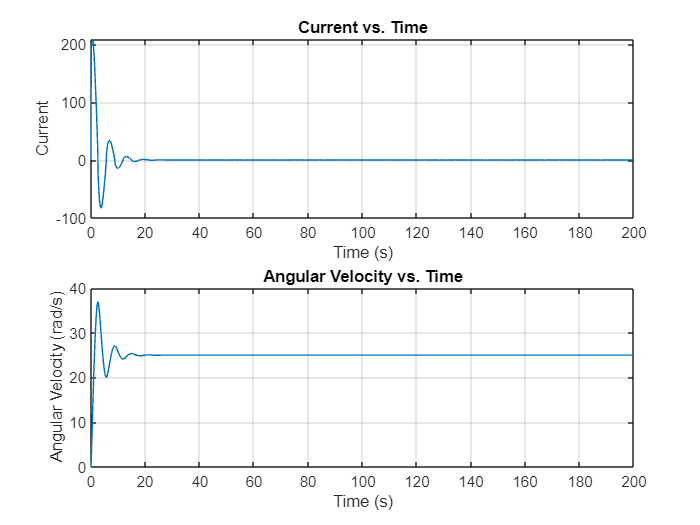

Ra = 0.1;La = 0.01;J = 10;B = 0.01;kb = 1;kt = 1;
global  error_current_prev init_speed init_current
 
%Outerloop PID
Kp_speed=5.5;
Ki_speed=0.055;
Kd_speed= 0.025;

%Innerloop PID
Kp_current= 4.25;
Ki_current=0.045;
Kd_current= 0.025;
 
ref_speed = 25;

error_current_prev = ref_speed- init_speed;

dt =0.1;
tspan = 0:dt:200;
[t, y] = ode45(@pmdc_system,tspan, [init_current; init_speed]);
 
% Current and Angular Velocity
ia = y(:, 1);  
w = y(:, 2);

% Plots
figure;
subplot(2, 1, 1);
plot(t, ia);
xlabel('Time (s)');
ylabel('Current');
title('Current vs. Time');
grid on;
subplot(2, 1, 2);
plot(t, w);
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');
title('Angular Velocity vs. Time');
grid on;

function dydt = pmdc_system(t,y)
global Ra La J B kb kt
global count ref_speed t_prev I_speed error_speed_prev I_current error_current_prev dt
global Kp_speed Ki_speed Kd_speed Kp_current Ki_current Kd_current

count = count+1;
ia = y(1);
w = y(2);
dydt = zeros(2, 1);
del_t= dt;
 
% Outer PID (Speed)
error_speed = ref_speed - w;
P_speed = Kp_speed * error_speed;
I_speed = I_speed + Ki_speed * error_speed * del_t;
D_speed = Kd_speed * ((error_speed - error_speed_prev)/ del_t );
control_speed = P_speed + I_speed + D_speed ;
 
% Inner PID
error_current= control_speed - ia;
P_current = Kp_current * error_current;
I_current = I_current + Ki_current * error_current * del_t;
D_current = Kd_current * ((error_current - error_current_prev)/del_t);
Vin = P_current + I_current+ D_current;
 
%System Dynamics
di_dt = (Vin - Ra * ia - kb * w ) / La;
dw_dt = (kt * ia - B * w ) / J;
 
dydt(1) = di_dt;
dydt(2) = dw_dt;
 
t_prev = t;
error_speed_prev = error_speed;
error_current_prev = error_current;

end

**PID Tuning done by Trial and error method**